## Fabrics names

We compute an array containing the name of the fabrics. Not computationnally useful but nice.

fabrics_names = {"id", "nearest_distance_mean", "nearest_distance_std"};
mode = ["mean", "std"];
for i = 1:3
    fabrics_names{end+1} = strcat("invariant-", int2str(i-1));
end

for k = 1:length(mode)
    for i = 1:6
        fabrics_names{end+1} = strcat("orientation-", int2str(i-1), "_", mode(k));
    end
end

for k = 1:length(mode)
    for i = 1:2
        fabrics_names{end+1} = strcat("aspectratio-", int2str(i-1), "_", mode(k));
    end
end
names = ["size", "solidity", "roundness"];
for i = 1:length(names)
    for k = 1:length(mode)
        fabrics_names{end+1} = strcat(names(i), "_", mode(k));
    end

end
fabrics_names{end+1} = "volume_fraction";
fabrics_names

fabrics_names = 1×29 cell array
    {["id"]}    {["nearest_distance_mean"]}    {["nearest_distance_std"]}    {["invariant-0"]}    {["invariant-1"]}    {["invariant-2"]}    {["orientation-0_mean"]}    {["orientation-1_mean"]}    {["orientation-2_mean"]}    {["orientation-3_mean"]}    {["orientation-4_mean"]}    {["orientation-5_mean"]}    {["orientation-0_std"]}    {["orientation-1_std"]}    {["orientation-2_std"]}    {["orientation-3_std"]}    {["orientation-4_std"]}    {["orientation-5_std"]}    {["aspectratio-0_mean"]}    {["aspectratio-1_mean"]}    {["aspectratio-0_std"]}    {["aspectratio-1_std"]}    {["size_mean"]}    {["size_std"]}    {["solidity_mean"]}    {["solidity_std"]}    {["roundness_mean"]}    {["roundness_std"]}    {["volume_fraction"]}


## Folder path

Feel free to changes the path if it doesn't fit your local folders !

topLevelFolder = append(fileparts(cd), "\REV1_600");
path_to_revs = append(topLevelFolder, "\REV1_6003D_model\");
path_to_fabrics =  append(topLevelFolder, "\fabrics.txt");
path_to_slices = append(topLevelFolder, "\REV1_600Slices");
path_to_instances = append(topLevelFolder, "REV1_600Instances");

fprintf("The revs are loaded at \n\t%s.\n" + ...
    "The farbrics are loaded and saved at \n\t%s.\n" + ...
    "The instances are loaded and saved at \n\t%s.\n" + ...
    "The sliced images are loaded and saved at \n\t%s", path_to_revs, path_to_fabrics, path_to_instances, path_to_slices);

The revs are loaded at 
	\\wsl.localhost\ubuntu\home\matias\microstructure-reconstruction\REV1_600\REV1_6003D_model\.
The farbrics are loaded and saved at 
	\\wsl.localhost\ubuntu\home\matias\microstructure-reconstruction\REV1_600\fabrics.txt.
The instances are loaded and saved at 
	\\wsl.localhost\ubuntu\home\matias\microstructure-reconstruction\REV1_600REV1_600Instances.
The sliced images are loaded and saved at 
	\\wsl.localhost\ubuntu\home\matias\microstructure-reconstruction\REV1_600\REV1_600Slices

## Already computed fabrics

We look for already computed fabrics. Thanks to this method, we can compute the 600 fabrics in multiple job, and we can stop any job and continue later.

files = dir(path_to_revs);
subFiles = files(contains({files.name}, ".stl") | contains({files.name}, ".STL"));

## Already computed sliced images

incoming cell

## What to compute ?

We define several boolean for what we want to compute. 

- `compute_fabrics` to know if we compute fabrics (thx captain obvious)

- `compute_sliced_images` to know if we compute sliced images.

- `display` to know if we display the triangulation of each `.stl`

compute_fabrics = true;

compute_sliced_images = false;
number_of_images_per_slice = 6;

display = false;

## Cell that computes the fabrics

Output to know how long does it take for each step

k = 2;
current_rev_file = strcat(subFiles(k).folder, "\", subFiles(k).name);
[filepath, name, ~] = fileparts(current_rev_file);
simplified_rev = rev(current_rev_file, false);
[cl, points] = simplified_rev.compute_mesh(0.25, 2);
save("REV1.mat", "simplified_rev")

Elapsed time is 40.044565 seconds.


a = load(strcat(path_to_meshes, "/Spec-102.mat")).cl

a = 10202×7 cell array
    {["elt_id"]}    {["material_id"]}    {["object_id"]}    {["upleft_node"]}    {["downleft_node"]}    {["downright_node"]}    {["upright_node"]}
    {[       1]}    {[            0]}    {[          0]}    {[            1]}    {[            103]}    {[             104]}    {[             2]}
    {[       2]}    {[            0]}    {[          0]}    {[            2]}    {[            104]}    {[             105]}    {[             3]}
    {[       3]}    {[            0]}    {[          0]}    {[            3]}    {[            105]}    {[             106]}    {[             4]}
    {[       4]}    {[            0]}    {[          0]}    {[            4]}    {[            106]}    {[             107]}    {[             5]}
    {[       5]}    {[            0]}    {[          0]}    {[            5]}    {[            107]}    {[             108]}    {[             6]}
    {[       6]}    {[            0]}    {[          0]}    {[            6]}    {[            

tic;
simplified_rev = load("rev.mat").simplified_rev;

simplified_rev =   rev with properties:

            path: "\\wsl.localhost\ubuntu\home\matias\microstructure-reconstruction\REV1_600\REV1_6003D_model\Spec-1.STL"
              TR: [214738×3 triangulation]
               P: [109100×3 double]
              CL: [214738×3 double]
          grains: {871×1 cell}
    total_volume: 7.0889e+05
     barycenters: [871×3 double]
           x_min: 0
           y_min: 0
           z_min: 0.0030
           x_max: 89.1646
           y_max: 89.1645
           z_max: 89.1685


[cl, points] = simplified_rev.compute_mesh(0.25, 2);

Elapsed time is 7.341647 seconds.


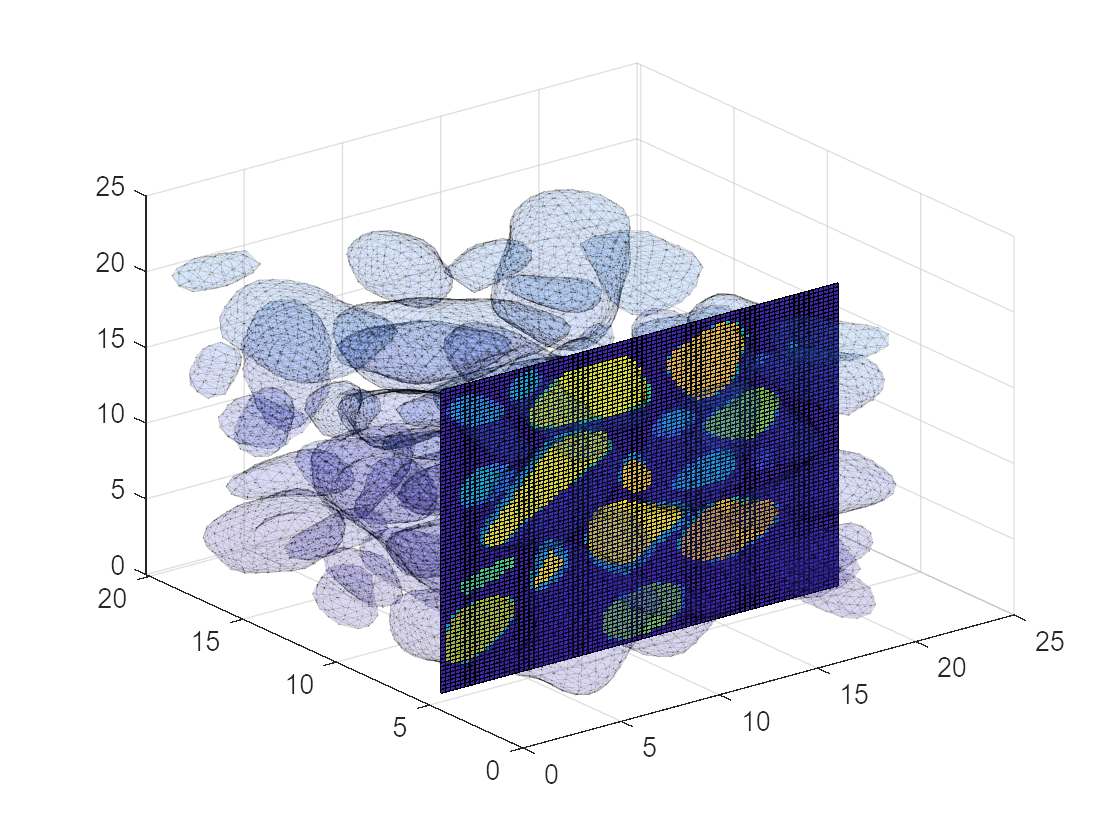

XI = 0.2500

ti = 0.25;
X = simplified_rev.x_min:ti:simplified_rev.x_max+ti;
Y = simplified_rev.y_min:ti:simplified_rev.y_max+ti;
Z = simplified_rev.z_min:ti:simplified_rev.z_max+ti;
[XI,YI, ZI] = meshgrid(X, Y, Z);
in = inpolyhedron(struct("faces", simplified_rev.grains{1}.CL, "vertices", simplified_rev.grains{1}.P), X, Y, Z) * 1;
for index = 2:length(simplified_rev.grains)
    current_in = inpolyhedron(struct("faces", simplified_rev.grains{index}.CL, "vertices", simplified_rev.grains{index}.P),X, Y, Z) * index;
    in = in + current_in;
end
figure;
% h = surf(simplified_rev.P(:, 1),simplified_rev.P(:, 2), simplified_rev.P(:, 3)); 
h = trisurf(simplified_rev.TR); hold on
set(h, 'FaceAlpha', 0.1,'EdgeAlpha', 0.1)
h1 = slice(XI, YI, ZI, in, [], [5], []);